%% AUTOENCODER SU VOLTI (MLX) senza SVD
% Addestra un semplice autoencoder fully‐connected direttamente sui pixel
clear; clc; close all;
rng(0);

%% 0) IMPOSTAZIONE AMBIENTE & CARTELLA RISULTATI
projectRoot = '/Users/…/ProgettoMetodi';
addpath(genpath(projectRoot));
this_folder  = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir')
    mkdir(results_path);
    fprintf('>>> Creo la cartella results\n');
end

%% 1) CARICAMENTO DATASET & MEAN FACE
fprintf('>>> Caricamento dataset...\n');  t_start = tic;

>>> Caricamento dataset...


load('dataset/volti_dataset_Yale.mat','A');  % carica A (m×n)
A = double(A)/255;
fprintf('   fatto in %.2f s\n', toc(t_start));

   fatto in 0.16 s



[m, n] = size(A);
img_h = 112;  img_w = 92;

fprintf('>>> Calcolo volto medio...\n');  t_start = tic;

>>> Calcolo volto medio...


mean_face = mean(A,2);
save(fullfile(results_path,'mean_face.mat'),'mean_face');
fprintf('   ok in %.2f s\n', toc(t_start));

   ok in 0.01 s



fprintf('>>> Centratura dati...\n');  t_start = tic;

>>> Centratura dati...


A_centered = A - mean_face;
fprintf('   ok in %.2f s\n', toc(t_start));

   ok in 0.01 s



%% 2) PREPARAZIONE DATI (flatten)
X_all = A_centered';     % [n_samples × input_dim]

%% 3) SPLIT TRAIN/TEST (80/20)
perm      = randperm(n);
n_train   = round(0.8 * n);
train_idx = perm(1:n_train);
test_idx  = perm(n_train+1:end);

X_train    = X_all(train_idx, :);    % [n_train × m]
X_test     = X_all(test_idx,  :);    % [n_test  × m]
orig_idx_test = test_idx;            % indici originali per valutazione

%% 4) PARAMETRI AUTOENCODER
epochs        = 50;
learning_rate = 0.01;
bottleneck    = 40;    % dimensione del codice

%% 5) TRAINING AUTOENCODER
fprintf('>>> Training autoencoder sui pixel centrati (bottleneck = %d)...\n', bottleneck);

>>> Training autoencoder sui pixel centrati (bottleneck = 40)...


t_start = tic;
% diventa:
[W_enc,b_enc,W_dec,b_dec,loss_history,test_loss_history] = ...
    autoencoder_train_2(X_train, X_test, mean_face, bottleneck, epochs, learning_rate);

[AE] Epoca  10/ 50: Train MSE=0.00000, Test MSE=0.00000
[AE] Epoca  20/ 50: Train MSE=0.00000, Test MSE=0.00000
[AE] Epoca  30/ 50: Train MSE=0.00000, Test MSE=0.00000
[AE] Epoca  40/ 50: Train MSE=0.00000, Test MSE=0.00000
[AE] Epoca  50/ 50: Train MSE=0.00000, Test MSE=0.00000


fprintf('   Fine training in %.2f s\n', toc(t_start));

   Fine training in 22.38 s


save(fullfile(results_path,'ae_weights.mat'),'W_enc','b_enc','W_dec','b_dec','loss_history');

%% 6) VALUTAZIONE SUL TEST SET
n_test    = numel(test_idx);
mse_pixel = zeros(n_test,1);

for i = 1:n_test
    idx     = orig_idx_test(i);
    x_in    = X_all(idx, :)';               % [m×1] centrato
    h       = max(0, W_enc * x_in + b_enc); % encoding + ReLU
    x_hat   = W_dec * h + b_dec;            % ricostruzione centrata
    x_rec   = x_hat + mean_face;            % ricostruzione pixel
    x_orig  = A(:, idx);                    % originale pixel
    err     = x_orig - x_rec;
    mse_pixel(i) = mean(err.^2);
end

mean_mse = mean(mse_pixel);
fprintf('\n>>> RISULTATI TEST SET:\n');


>>> RISULTATI TEST SET:


fprintf('    MSE medio sul test set: %.6f\n', mean_mse);

    MSE medio sul test set: 0.000001


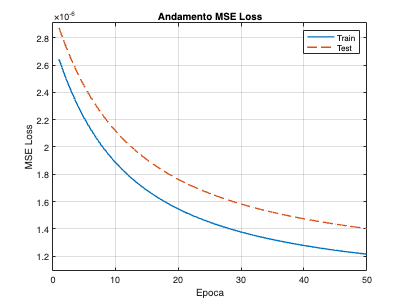



%% 7) PLOT DELL’ANDAMENTO DELLA MSE LOSS
figure('Name','AE: Train vs Test MSE','NumberTitle','off');
plot(1:epochs, loss_history,      '-','LineWidth',1.5); hold on;
plot(1:epochs, test_loss_history, '--','LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss');
legend('Train','Test','Location','northeast');
title('Andamento MSE Loss');
grid on;
% regola i limiti per rendere visibile la test loss orizzontale
ymin = min([loss_history, test_loss_history]) * 0.9;
ymax = max(loss_history) * 1.1;
ylim([ymin, ymax]);

saveas(gcf, fullfile(results_path,'ae_loss_trend.png'));


fprintf('>>> Fine script (totale %.2f s)\n', toc);

>>> Fine script (totale 3296.19 s)
